optoChan_0Ind = 133;
facemotionThresh = 1000;
serverPath = 'G:\ChR2_dual_summer_2023';
layerBorders = [-inf 100; 101 300; 301 450; 451 650; 651 900; 1100 inf];

## Animal 6560

Day 4 - Session A

Processing trial 82 from 82



cfg = struct with fields:
    showcallinfo: 'no'


the input is spike data with 43 channels


Please wait...



cfg = struct with fields:
    showcallinfo: 'no'


the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



the input is spike data with 43 channels


Please wait...

the input is spike data with 43 channels


Please wait...



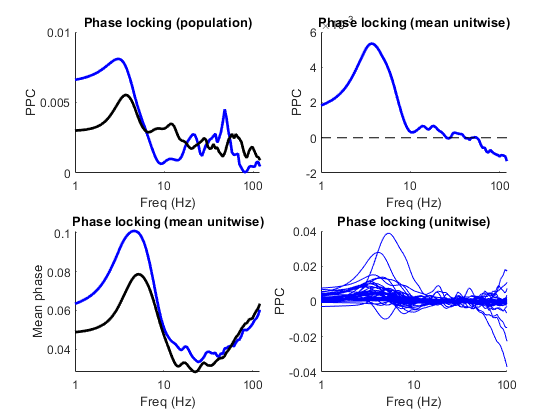

basepath = [serverPath '\6560\JR_23_08_17_ChR2_dual_animal_6560_session_A\JR_23_08_17_ChR2_dual_animal_6560_session_A_230817_112238'];

chanDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(chanDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);

spikes = bz_GetSpikes('basepath', char(basepath),'spikeGroups',1);

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);
optoInts = getOptoInts(char(basepath), optostim, facemotionThresh);

% PPCAnalysis(optoInts, spikes, lfp, L5Chan)
 Animal6560a = PPCAnalysis(optoInts, spikes, lfpReref, L5Chan, co, chanDepths);

Day 2 - Session A

basepath = [serverPath '\6560\JR_23_08_15_ChR2_dual_animal_6560_session_A\JR_23_08_15_ChR2_dual_animal_6560_session_A_230815_100405'];

chanDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(chanDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);

spikes = bz_GetSpikes('basepath', char(basepath),'spikeGroups',1);

loading spikes from cellinfo file..



% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


the input is spike data with 5 channels


making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
the input is raw data with 1 channels and 1 trials


> In fixsampleinfo (line 102)
  In ft_datatype_raw (line 148)
  In 

cfg = struct with fields:
    showcallinfo: 'no'


the input is raw data with 1 channels and 79 trials
the input is spike data with 5 channels


Please wait...
Processing trial 4 from 79
setting 1 points from channelProcessing trial 79 from 79



cfg = struct with fields:
    showcallinfo: 'no'


the input is spike data with 5 channels


Please wait...



cfg = struct with fields:
    showcallinfo: 'no'


the input is spike data with 5 channels


Please wait...



the input is spike data with 5 channels


Please wait...

the input is spike data with 5 channels


Please wait...



the input is spike data with 5 channels


Please wait...

the input is spike data with 5 channels


Please wait...



the input is spike data with 5 channels


Please wait...

the input is spike data with 5 channels


Please wait...



the input is spike data with 5 channels


Please wait...

the input is spike data with 5 channels


Please wait...



the input is spike data with 5 channels


Please wait...

the input is spike data with 5 channels


Please wait...



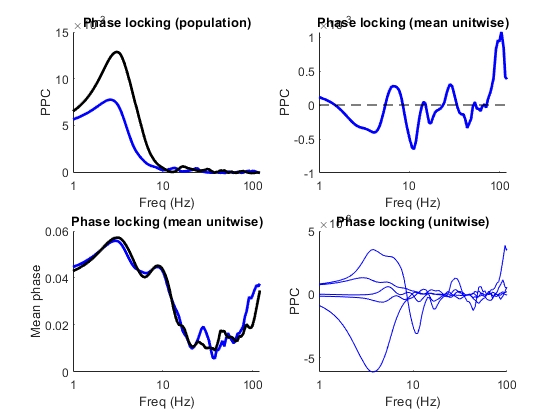

optoInts = getOptoInts(char(basepath), optostim, facemotionThresh);

% PPCAnalysis(optoInts, spikes, lfp, L5Chan)
Animal6560b = PPCAnalysis(optoInts, spikes, lfpReref, L5Chan, co, chanDepths);

## Animal 6556

Day 2 - Session A

basepath = [serverPath '\6556\JR_23_08_22_ChR2_dual_animal_6556_session_A\JR_23_08_22_ChR2_dual_animal_6556_session_A_230822_100542'];

chanDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(chanDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);

spikes = bz_GetSpikes('basepath', char(basepath),'spikeGroups',1);

loading spikes from cellinfo file..



% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


optoInts = getOptoInts(char(basepath), optostim, facemotionThresh);


the input is spike data with 35 channels


making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making sel

> In fixsampleinfo (line 102)
  In ft_datatype_raw (line 148)
  In 

cfg = struct with fields:
    showcallinfo: 'no'


the input is raw data with 1 channels and 105 trials
the input is spike data with 35 channels


Please wait...
Processing trial 105 from 105



cfg = struct with fields:
    showcallinfo: 'no'


the input is spike data with 35 channels


Please wait...



cfg = struct with fields:
    showcallinfo: 'no'


the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



the input is spike data with 35 channels


Please wait...

the input is spike data with 35 channels


Please wait...



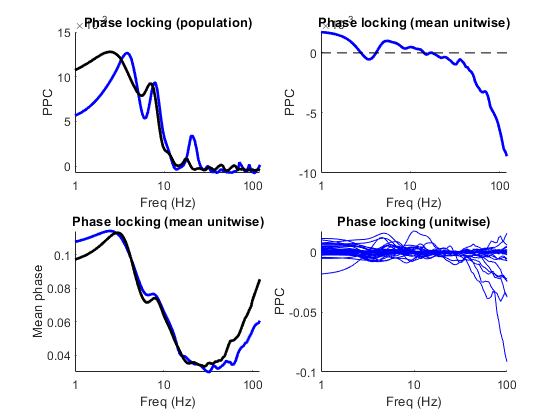

Animal6556a = struct with fields:
      PPCStim: [1×100 double]
     PPCSpont: [1×100 double]
        freqs: [1×100 double]
        layer: [2 2 2 2 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 4 4 4 5 4 4 3 2 2 4 3 2 2 4]
    MeanAngle: [1×1 struct]


% PPCAnalysis(optoInts, spikes, lfp, L5Chan)
Animal6556a = PPCAnalysis(optoInts, spikes, lfpReref, L5Chan, co, chanDepths)

Day 2 - Session C

basepath = [serverPath '\6556\JR_23_08_23_ChR2_dual_animal_6556_session_C\JR_23_08_23_ChR2_dual_animal_6556_session_C_230823_100827'];

chanDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(chanDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);

spikes = bz_GetSpikes('basepath', char(basepath),'spikeGroups',1);

loading spikes from cellinfo file..



% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


the input is spike data with 41 channels


making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making sel

> In fixsampleinfo (line 102)
  In ft_datatype_raw (line 148)
  In 

cfg = struct with fields:
    showcallinfo: 'no'


the input is raw data with 1 channels and 115 trials
the input is spike data with 41 channels


Please wait...
Processing trial 115 from 115



cfg = struct with fields:
    showcallinfo: 'no'


the input is spike data with 41 channels


Please wait...



cfg = struct with fields:
    showcallinfo: 'no'


the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



the input is spike data with 41 channels


Please wait...

the input is spike data with 41 channels


Please wait...



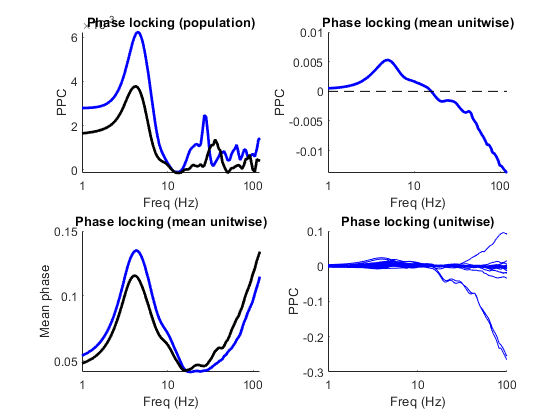

optoInts = getOptoInts(char(basepath), optostim, facemotionThresh);

% PPCAnalysis(optoInts, spikes, lfp, L5Chan)
Animal6556b = PPCAnalysis(optoInts, spikes, lfpReref, L5Chan, co, chanDepths);

Day 4 - Session A

basepath = [serverPath '\6556\JR_23_08_24_ChR2_dual_animal_6556_session_A\JR_23_08_24_ChR2_dual_animal_6556_session_A_230824_105116'];

chanDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(chanDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);

spikes = bz_GetSpikes('basepath', char(basepath),'spikeGroups',1);

loading spikes from cellinfo file..



% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


the input is spike data with 23 channels


making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
the input is raw data with 1 channels and 1 trials


> In fixsampleinfo (line 102)
  In ft_datatype_raw (line 148)
  In 

cfg = struct with fields:
    showcallinfo: 'no'


the input is raw data with 1 channels and 95 trials
the input is spike data with 23 channels


Please wait...
Processing trial 95 from 95



cfg = struct with fields:
    showcallinfo: 'no'


the input is spike data with 23 channels


Please wait...



cfg = struct with fields:
    showcallinfo: 'no'


the input is spike data with 23 channels


Please wait...



the input is spike data with 23 channels


Please wait...

the input is spike data with 23 channels


Please wait...



the input is spike data with 23 channels


Please wait...

the input is spike data with 23 channels


Please wait...



the input is spike data with 23 channels


Please wait...

the input is spike data with 23 channels


Please wait...



the input is spike data with 23 channels


Please wait...

the input is spike data with 23 channels


Please wait...



the input is spike data with 23 channels


Please wait...

the input is spike data with 23 channels


Please wait...



the input is spike data with 23 channels


Please wait...

the input is spike data with 23 channels


Please wait...



the input is spike data with 23 channels


Please wait...

the input is spike data with 23 channels


Please wait...



the input is spike data with 23 channels


Please wait...

the input is spike data with 23 channels


Please wait...



the input is spike data with 23 channels


Please wait...

the input is spike data with 23 channels


Please wait...



the input is spike data with 23 channels


Please wait...

the input is spike data with 23 channels


Please wait...



the input is spike data with 23 channels


Please wait...

the input is spike data with 23 channels


Please wait...



the input is spike data with 23 channels


Please wait...

the input is spike data with 23 channels


Please wait...



the input is spike data with 23 channels


Please wait...

the input is spike data with 23 channels


Please wait...



the input is spike data with 23 channels


Please wait...

the input is spike data with 23 channels


Please wait...



the input is spike data with 23 channels


Please wait...

the input is spike data with 23 channels


Please wait...



the input is spike data with 23 channels


Please wait...

the input is spike data with 23 channels


Please wait...



the input is spike data with 23 channels


Please wait...

the input is spike data with 23 channels


Please wait...



the input is spike data with 23 channels


Please wait...

the input is spike data with 23 channels


Please wait...



the input is spike data with 23 channels


Please wait...

the input is spike data with 23 channels


Please wait...



the input is spike data with 23 channels


Please wait...

the input is spike data with 23 channels


Please wait...



the input is spike data with 23 channels


Please wait...

the input is spike data with 23 channels


Please wait...



the input is spike data with 23 channels


Please wait...

the input is spike data with 23 channels


Please wait...



the input is spike data with 23 channels


Please wait...

the input is spike data with 23 channels


Please wait...



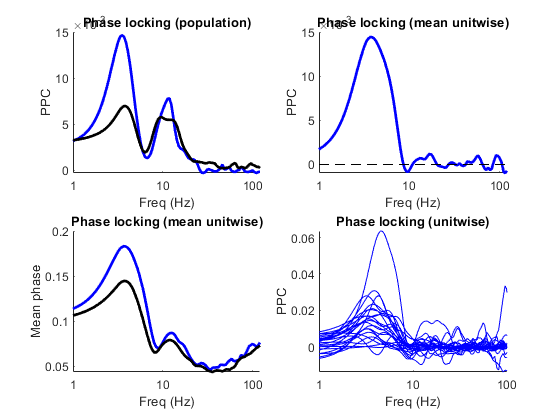

optoInts = getOptoInts(char(basepath), optostim, facemotionThresh);

% PPCAnalysis(optoInts, spikes, lfp, L5Chan)
Animal6556c = PPCAnalysis(optoInts, spikes, lfpReref, L5Chan, co, chanDepths);

Day 5 - Session C

basepath = [serverPath '\6556\JR_23_08_25_ChR2_dual_animal_6556_session_C\JR_23_08_25_ChR2_dual_animal_6556_session_C_230825_104818'];

chanDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(chanDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);

spikes = bz_GetSpikes('basepath', char(basepath),'spikeGroups',1);

loading spikes from cellinfo file..



% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


optoInts = getOptoInts(char(basepath), optostim, facemotionThresh);

% PPCAnalysis(optoInts, spikes, lfp, L5Chan)

the input is spike data with 29 channels


making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
the input is raw data with 1 channels and 1 trials


> In fixsampleinfo (line 102)
  In ft_datatype_raw (line 148)
  In 

cfg = struct with fields:
    showcallinfo: 'no'


the input is raw data with 1 channels and 109 trials
the input is spike data with 29 channels


Please wait...
Processing trial 109 from 109



cfg = struct with fields:
    showcallinfo: 'no'


the input is spike data with 29 channels


Please wait...



cfg = struct with fields:
    showcallinfo: 'no'


the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



the input is spike data with 29 channels


Please wait...

the input is spike data with 29 channels


Please wait...



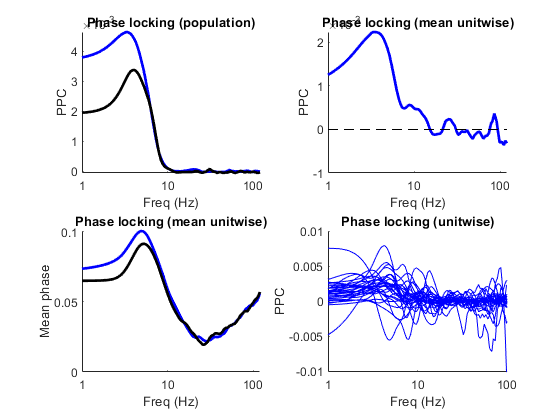

Animal6556d = PPCAnalysis(optoInts, spikes, lfpReref, L5Chan, co, chanDepths);

## Animal 7149

Day 2 - Session A

basepath = [serverPath '\7149\JR_23_09_06_ChR2_dual_animal_7149_session_A\JR_23_09_06_ChR2_dual_animal_7149_session_A_230906_103733'];

chanDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(chanDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);

spikes = bz_GetSpikes('basepath', char(basepath),'spikeGroups',1);

loading spikes from cellinfo file..



% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


optoInts = getOptoInts(char(basepath), optostim, facemotionThresh);


the input is spike data with 98 channels


making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making sel

> In fixsampleinfo (line 102)
  In ft_datatype_raw (line 148)
  In 

cfg = struct with fields:
    showcallinfo: 'no'


the input is raw data with 1 channels and 29 trials
the input is spike data with 98 channels


Please wait...
Processing trial 29 from 29



cfg = struct with fields:
    showcallinfo: 'no'


the input is spike data with 98 channels


Please wait...



cfg = struct with fields:
    showcallinfo: 'no'


the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



the input is spike data with 98 channels


Please wait...

the input is spike data with 98 channels


Please wait...



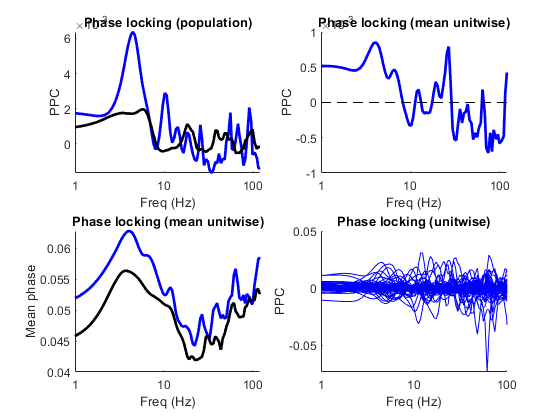

Animal7149a = struct with fields:
      PPCStim: [1×100 double]
     PPCSpont: [1×100 double]
        freqs: [1×100 double]
        layer: [3 3 1 1 3 3 1 1 1 3 3 3 1 3 2 4 2 4 2 4 4 2 2 2 2 2 2 4 2 2 2 4 4 4 2 2 4 4 4 2 2 2 2 4 4 4 2 2 2 5 3 3 5 3 3 3 5 5 5 4 4 4 4 6 4 4 6 4 6 5 5 5 6 6 5 6 5 5 6 6 5 5 5 6 6 6 6 6 6 2 5 6 6 5 6 1 3 4]
    MeanAngle: [1×1 struct]


% PPCAnalysis(optoInts, spikes, lfp, L5Chan)
Animal7149a = PPCAnalysis(optoInts, spikes, lfpReref, L5Chan, co, chanDepths)

Day 3 - Session C

basepath = [serverPath '\7149\JR_23_09_07_ChR2_dual_animal_7149_session_C\JR_23_09_07_ChR2_dual_animal_7149_session_C_230907_100125'];

chanDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(chanDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);

spikes = bz_GetSpikes('basepath', char(basepath),'spikeGroups',1);

loading spikes from cellinfo file..



% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


the input is spike data with 32 channels


making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
the input is raw data with 1 channels an

> In fixsampleinfo (line 102)
  In ft_datatype_raw (line 148)
  In 

cfg = struct with fields:
    showcallinfo: 'no'


the input is raw data with 1 channels and 93 trials
the input is spike data with 32 channels


Please wait...
Processing trial 93 from 93



cfg = struct with fields:
    showcallinfo: 'no'


the input is spike data with 32 channels


Please wait...



cfg = struct with fields:
    showcallinfo: 'no'


the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



the input is spike data with 32 channels


Please wait...

the input is spike data with 32 channels


Please wait...



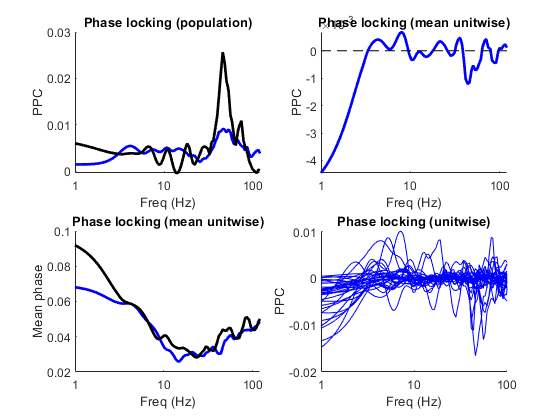

optoInts = getOptoInts(char(basepath), optostim, facemotionThresh);

% PPCAnalysis(optoInts, spikes, lfp, L5Chan)
Animal7149b = PPCAnalysis(optoInts, spikes, lfpReref, L5Chan, co, chanDepths);

## Animal 7158

Day 2 - Session A

basepath = [serverPath '\7158\JR_23_09_11_ChR2_dual_animal_7158_session_A\JR_23_09_11_ChR2_dual_animal_7158_session_A_230911_100123'];


chanDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(chanDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);

spikes = bz_GetSpikes('basepath', char(basepath),'spikeGroups',1);

loading spikes from cellinfo file..



% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


optoInts = getOptoInts(char(basepath), optostim, facemotionThresh);


% PPCAnalysis(optoInts, spikes, lfp, L5Chan)
Animal7158a = PPCAnalysis(optoInts, spikes, lfpReref, L5Chan, co, chanDepths); 

the input is spike data with 89 channels


making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making selection in timestamp
making sel

> In fixsampleinfo (line 102)
  In ft_datatype_raw (line 148)
  In 

cfg = struct with fields:
    showcallinfo: 'no'


the input is raw data with 1 channels and 58 trials
the input is spike data with 89 channels


Please wait...
Processing trial 58 from 58



cfg = struct with fields:
    showcallinfo: 'no'


the input is spike data with 89 channels


Please wait...



cfg = struct with fields:
    showcallinfo: 'no'


the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Please wait...



the input is spike data with 89 channels


Please wait...

the input is spike data with 89 channels


Day 3 - Session C

basepath = [serverPath '\7158\JR_23_09_12_ChR2_dual_animal_7158_session_C\JR_23_09_12_ChR2_dual_animal_7158_session_C_230912_094221'];

chanDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(chanDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);

spikes = bz_GetSpikes('basepath', char(basepath),'spikeGroups',1);

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);
optoInts = getOptoInts(char(basepath), optostim, facemotionThresh);

% PPCAnalysis(optoInts, spikes, lfp, L5Chan)
Animal7158b = PPCAnalysis(optoInts, spikes, lfpReref, L5Chan, co, chanDepths);

Day 4 - Session A

basepath = [serverPath '\7158\JR_23_09_13_ChR2_dual_animal_7158_session_A\JR_23_09_13_ChR2_dual_animal_7158_session_A_230913_101804'];

chanDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(chanDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);

spikes = bz_GetSpikes('basepath', char(basepath),'spikeGroups',1);

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);
optoInts = getOptoInts(char(basepath), optostim, facemotionThresh);

% PPCAnalysis(optoInts, spikes, lfp, L5Chan)
Animal7158c = PPCAnalysis(optoInts, spikes, lfpReref, L5Chan, co, chanDepths);

## New data for revision

data_loc = "G:\revision_opto_sessions";
optoChan_0Ind = 69;
facemotionThresh = 1000;

## Animal 6575

Day 1 - Session A - 04/15/24

basepath = data_loc + '\6575\JR_24_04_15_SSTnNOS_ChR2_6575_session_A\JR_24_04_15_SSTnNOS_ChR2_6575_session_A_240415_105602'

chanDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(chanDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);

spikes = bz_GetSpikes('basepath', char(basepath),'spikeGroups',1);

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);
optoInts = getOptoInts(char(basepath), optostim, facemotionThresh);

% PPCAnalysis(optoInts, spikes, lfp, L5Chan)
Animal6575a = PPCAnalysis(optoInts, spikes, lfpReref, L5Chan, co, chanDepths);

Day 5 - Session A - 04/19/24

basepath = data_loc + '\6575\JR_24_04_19_SSTnNOS_ChR2_6575_session_A\JR_24_04_19_SSTnNOS_ChR2_6575_session_A_240419_085822';

chanDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(chanDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);

spikes = bz_GetSpikes('basepath', char(basepath),'spikeGroups',1);

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);
optoInts = getOptoInts(char(basepath), optostim, facemotionThresh);

% PPCAnalysis(optoInts, spikes, lfp, L5Chan)
Animal6575b = PPCAnalysis(optoInts, spikes, lfpReref, L5Chan, co, chanDepths);

## Animal 6576

Day 2 - Session A - 04/16/24

basepath = data_loc + '\6576\JR_24_04_16_SSTnNOS_ChR2_6576_session_A\JR_24_04_16_SSTnNOS_ChR2_6576_session_A_240416_103011';

chanDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(chanDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);

spikes = bz_GetSpikes('basepath', char(basepath),'spikeGroups',1);

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);
optoInts = getOptoInts(char(basepath), optostim, facemotionThresh);

% PPCAnalysis(optoInts, spikes, lfp, L5Chan)
Animal6576a = PPCAnalysis(optoInts, spikes, lfpReref, L5Chan, co, chanDepths);

## Animal 6692

Day 5 - Session A - 03/29/24

basepath = data_loc + '\6692\JR_24_03_29_SSTnNOS_ChR2_6692_session_A\JR_24_03_29_SSTnNOS_ChR2_6692_session_A_240329_085446';

chanDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(chanDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);

spikes = bz_GetSpikes('basepath', char(basepath),'spikeGroups',1);

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);
optoInts = getOptoInts(char(basepath), optostim, facemotionThresh);

% PPCAnalysis(optoInts, spikes, lfp, L5Chan)
Animal6692a = PPCAnalysis(optoInts, spikes, lfpReref, L5Chan, co, chanDepths);

Day 3 (second craniotomy) - Session A - 04/03/24

% basepath = data_loc + '\6692\JR_24_04_03_SSTnNOS_ChR2_6692_right_session_A\JR_24_04_03_SSTnNOS_ChR2_6692_right_session_A_240403_100421';

## Animal 6695

Day 4 - Session A - 03/29/24

% basepath = data_loc + '\6695\JR_24_03_29_SSTnNOS_ChR2_6695_session_A\JR_24_03_29_SSTnNOS_ChR2_6695_session_A_240329_123702';

Day 3 (second crainotomy) - Session A - 04/03/24

basepath = data_loc + '\6695\JR_24_04_03_SSTnNOS_ChR2_6695_right_session_A\JR_24_04_03_SSTnNOS_ChR2_6695_right_session_A_240403_140338';

chanDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(chanDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);

spikes = bz_GetSpikes('basepath', char(basepath),'spikeGroups',1);

% Get details of optogenetic stimulation
% optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);
load(basepath + '\' + bz_BasenameFromBasepath(basepath) + ".optostim.mat")
optoInts = getOptoInts(basepath, optostim, facemotionThresh);

% PPCAnalysis(optoInts, spikes, lfp, L5Chan)
Animal6695a = PPCAnalysis(optoInts, spikes, lfpReref, L5Chan, co, chanDepths);

## Animal 6750

Day 2 - Session A - 04/16/24

basepath = data_loc + '\6750\JR_24_04_16_SSTnNOS_ChR2_6750_session_A\JR_24_04_16_SSTnNOS_ChR2_6750_session_A_240416_145805';

chanDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(chanDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);

spikes = bz_GetSpikes('basepath', char(basepath),'spikeGroups',1);

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);
optoInts = getOptoInts(char(basepath), optostim, facemotionThresh);

% PPCAnalysis(optoInts, spikes, lfp, L5Chan)
Animal6750a = PPCAnalysis(optoInts, spikes, lfpReref, L5Chan, co, chanDepths);

## Animal 6759

Day 1 - Session A - 04/15/24

basepath = data_loc + '\6759\JR_24_04_15_SSTnNOS_ChR2_6759_session_A\JR_24_04_15_SSTnNOS_ChR2_6759_session_A_240415_145147';

chanDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(chanDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);

spikes = bz_GetSpikes('basepath', char(basepath),'spikeGroups',1);

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);
optoInts = getOptoInts(char(basepath), optostim, facemotionThresh);

% PPCAnalysis(optoInts, spikes, lfp, L5Chan)
% Animal6759a = PPCAnalysis(optoInts, spikes, lfpReref, L5Chan, co, chanDepths);

Day 5 - Session A - 04/19/24

basepath = data_loc + '\6759\JR_24_04_19_SSTnNOS_ChR2_6759_session_A\JR_24_04_19_SSTnNOS_ChR2_6759_session_A_240419_131907';

chanDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(chanDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

lfp = bz_GetLFP(0:63, 'basepath',char(basepath));
lfpReref = lfp;
lfpReref.data = lfp.data - median(lfp.data,2);

spikes = bz_GetSpikes('basepath', char(basepath),'spikeGroups',1);

% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(char(basepath), optoChan_0Ind);
optoInts = getOptoInts(char(basepath), optostim, facemotionThresh);

% PPCAnalysis(optoInts, spikes, lfp, L5Chan)
Animal6759b = PPCAnalysis(optoInts, spikes, lfpReref, L5Chan, co, chanDepths);

animals = [Animal6556a, Animal6556b, Animal6556c, Animal6556d, Animal6560a, Animal6560b, Animal7149a, Animal7149b, Animal7158a, Animal7158b, Animal7158c,...
    Animal6575a, Animal6575b, Animal6576a, Animal6692a,...
    Animal6695a, Animal6750a, Animal6759b];

MeanAngle.stim = [];
MeanAngle.spont = [];
layer = [];
sessionID = [];

for i = 1:length(animals)
    PPC.stim(i,:) = animals(i).PPCStim;
    PPC.spont(i,:) = animals(i).PPCSpont;
    MeanAngle.stim = [MeanAngle.stim; animals(i).MeanAngle.stim];
    MeanAngle.spont = [MeanAngle.spont; animals(i).MeanAngle.spont];
    layer = [layer animals(i).layer];
    sessionID = [sessionID, i*ones(1,length(animals(i).layer))];
end

figure; hold on
shadedErrorBar(Animal6556a.freqs, mean(PPC.stim,1), std(PPC.stim,0,1)./sqrt(length(animals)),'lineprops','b')
shadedErrorBar(Animal6556a.freqs, mean(PPC.spont,1), std(PPC.spont,0,1)./sqrt(length(animals)),'lineprops','k')
xlim([0 100])
set(gca,'xscale', 'log')
xticks([1 10 100])
xticklabels([1 10 100])
title('Phase locking (population)')
xlabel("Freq (Hz)")
ylabel("PPC")

% subplot(1,2,2); hold on
% plot(Animal6556a.freqs, mean(PPC.stim,1) - mean(PPC.spont,1),'b','LineWidth',2)
% % plot(Animal6556.freqs, mean(PPC.spont,1),'k','LineWidth',2)
% xlim([0 100])
% set(gca,'xscale', 'log')
% xticks([1 10 100])
% xticklabels([1 10 100])
% title('Phase locking (unitwise)')
% xlabel("Freq (Hz)")
% ylabel("PPC")

figure
subplot(2,2,1); hold on
shadedErrorBar(Animal6556a.freqs, mean(MeanAngle.stim,1), std(MeanAngle.stim,0,1)./sqrt(length(MeanAngle.stim)),'lineprops','b')
shadedErrorBar(Animal6556a.freqs, mean(MeanAngle.spont,1), std(MeanAngle.spont,0,1)./sqrt(length(MeanAngle.stim)),'lineprops','k')
xlim([0 60])
set(gca,'xscale', 'log')
xticks([1 10 40])
xticklabels([1 10 40])
title('Phase locking (unitwise)')
xlabel("Freq (Hz)")
ylabel("Mean resultant length")

subplot(2,2,2); hold on
shadedErrorBar(Animal6556a.freqs, mean(MeanAngle.stim - MeanAngle.spont,1), ...
    std(MeanAngle.stim - MeanAngle.spont,0,1)./sqrt(length(MeanAngle.stim)),'lineprops','b')
xlim([1 100])
set(gca,'xscale', 'log')
xticks([1 10 40])
xticklabels([1 10 40])
title('Phase locking (unitwise)')
xlabel("Freq (Hz)")
ylabel("Change with stim")
plot(xlim, [0 0], 'k--')

deltamask = Animal6556a.freqs < 4;
deltalock.stim = trapz(Animal6556a.freqs(deltamask), MeanAngle.stim(:,deltamask), 2) / 4;
deltalock.spont = trapz(Animal6556a.freqs(deltamask), MeanAngle.spont(:,deltamask), 2) / 4;

subplot(2,2,3); hold on
% bar([mean(deltalock.spont) mean(deltalock.stim)],...
%     'FaceColor','flat','EdgeColor','none')
% errorbar([mean(deltalock.spont) mean(deltalock.stim)], [std(deltalock.spont) std(deltalock.stim)]./sqrt(length(deltalock.stim)),...
%     'k','LineWidth',2,'LineStyle','none')
% edges = 0:.07:.6;
% histogram(deltalock.spont,edges,'EdgeColor','none','FaceColor','k','FaceAlpha',.5)
% histogram(deltalock.stim,edges,'EdgeColor','none','FaceColor','b','FaceAlpha',.5)
edges = -.15:.05:.15;
histogram(deltalock.stim - deltalock.spont,edges,'EdgeColor','none','FaceColor','b','FaceAlpha',.5)
plot([0 0],ylim,'k--')
xlabel('Change')
ylabel('Count')

subplot(2,2,4); hold on
bar([mean(deltalock.stim - deltalock.spont)],...
    'FaceColor','b','EdgeColor','none')
errorbar(mean(deltalock.stim - deltalock.spont), std(deltalock.stim - deltalock.spont)./sqrt(length(deltalock.stim)),...
    'k','LineWidth',2,'LineStyle','none')
ylabel('Change')

disp("Paired t-test on delta band phase locking:")
[h p] = ttest(deltalock.stim, deltalock.spont)

bandlims = [6,10; 12,30; 30,70; 100,140];
bandmask = false(size(bandlims,1),100);
bandAngleDiff = [];
for i = 1:size(bandlims,1)
    [~, bandmask(i,:)] = RestrictInts(Animal6556a.freqs',bandlims(i,:));
    bandfreq = Animal6556a.freqs(bandmask(i,:));
    bandAngleDiff(i,:) = ...
        trapz(bandfreq, MeanAngle.stim(:,bandmask(i,:)),2)...
        ./ trapz(bandfreq, MeanAngle.spont(:,bandmask(i,:)),2);
end


% % Sample data
% n_bands = 5; % Number of bands
% n_neurons = 10; % Number of neurons
% bandAngleDiff = rand(n_bands, n_neurons); % Random data for demonstration
% layer = randi([1, 3], 1, n_neurons); % Random layer indices (1 to 3)

n_bands = length(bandlims);

% Unique layers
unique_layers = unique(layer);
mean_values = zeros(length(unique_layers), n_bands);

% Calculate mean for each layer
for i = 1:length(unique_layers)
    mean_values(i, :) = mean(bandAngleDiff(:, layer == unique_layers(i)), 2);
end


% Create heatmap
figure
h = heatmap(unique_layers, 1:n_bands, mean_values');
xlabel('Layer');
ylabel('Band');
% colormap redblue
% set(gca,'ColorLimits',[0 1.4])
xlim([2 6])
set(gca,'XdisplayLabels',{"1","2/3","4","5","6","HPC"})
set(gca,'YDisplayLabels',{"Delta","Theta","Low Gamma","High Gamma"})

tbl = table(...
    'VariableNames',{'Delta_change','Theta_change','Low_G_change','High_G_change','Layer','SessionID'},...
    'Size',[length(layer),6],...
    'VariableTypes', {'double', 'double', 'double', 'double', 'categorical', 'categorical'});
tbl.Delta_change = bandAngleDiff(1,:)';
tbl.Theta_change = bandAngleDiff(2,:)';
tbl.Low_G_change = bandAngleDiff(3,:)';
tbl.High_G_change = bandAngleDiff(4,:)';
tbl.Layer = categorical(layer)';
tbl.SessionID = sessionID';

tbl2 = table(...
    'VariableNames',{'Locking_change','Band','UnitID','Layer','SessionID','DummyStim'},...
    'Size',[numel(bandAngleDiff),6],...
    'VariableTypes', {'double','categorical','categorical','categorical','categorical', 'logical'});
tbl2.Locking_change = bandAngleDiff(:);
tbl2.Band = categorical(repelem(["Delta","Theta","Low_gamma",'High_gamma'],length(layer)))';
tbl2.UnitID = categorical(repelem(1:length(layer),4))';
tbl2.Layer = categorical(repelem(layer,4))';
tbl2.SessionID = categorical(repelem(sessionID,4))';
tbl2.DummyStim(:) = true;

tblDummy = tbl2;
tblDummy.Locking_change(:) = 0;
tblDummy.DummyStim(:) = false;

tbl3 = vertcat(tbl2, tblDummy);

mdl = fitlme(tbl3, ...
    'Locking_change ~ 1 + Band + Layer + DummyStim + (DummyStim|Layer) + (DummyStim|Band) + (DummyStim|SessionID) + (1|SessionID) + (1|UnitID) + (Band|Layer)')

mdl

mdl2 = fitlme(tbl2,...
    'Locking_change ~ 1 + Band + Layer + (Band|SessionID) + (Layer|SessionID) + (Band|UnitID) + (Layer|UnitID) + (1|SessionID) + (1|UnitID) + (Band|Layer)');

mdl2

function output = PPCAnalysis(optoInts, spikes, lfp, L5Chan, channelOrder, chanDepths)

% Concatenate optoInts and add trial labels to make trial mat
trialMat = vertcat(...
    horzcat(optoInts.NREMStim, zeros(length(optoInts.NREMStim),1),ones(length(optoInts.NREMStim),1).*1),... % Stim trials labeled 1
    horzcat(optoInts.NREMSpont, zeros(length(optoInts.NREMSpont),1),ones(length(optoInts.NREMSpont),1).*2)); % Spont trials labeled 2

trialMat(diff(trialMat(:,1:2),1,2) < 10,:) = [];


% Make spike trials
cfg.trl = trialMat;
cfg.showcallinfo='no';
cfg.timestampspersecond = 1;
spikes_ft.timestamp = spikes.times;
spikes_ft.label = cellstr("unit_" + spikes.UID);

spike_trials = ft_spike_maketrials(cfg, spikes_ft);

clearvars cfg

% Make LFP trials
data.trial{1} = double(lfp.data(:, L5Chan + 1))';
data.time{1}  = lfp.timestamps';
data.fsample = lfp.samplingRate;
data.label{1} = 'Layer_5';

trialMat_samples = trialMat;
trialMat_samples(:,1:3) = round(trialMat_samples(:,1:3) * lfp.samplingRate);

cfg.trl = trialMat_samples;
cfg.showcallinfo='no';
data = ft_redefinetrial(cfg,data);

% Calculate spike triggered spectrum
cfg = [];
cfg.showcallinfo='no'
cfg.method = 'mtmconvol';
foi = logspace(log10(1),log10(120),100);
cfg.foi = foi;
cfg.tapsmofrq = 4 * ones(size(foi));
cfg.taper = 'hanning';
cfg.t_ftimwin = 9./foi;
cfg.channel = {'Layer_5'};
sts = ft_spiketriggeredspectrum(cfg, data, spike_trials);
% Calculate PPC for stim trials
cfg = [];
cfg.showcallinfo='no'
cfg.method = 'ppc0';
cfg.channel = {'Layer_5'};
cfg.avgoverchan = 'unweighted';
cfg.timwin = 'all';
cfg.trials = trialMat(:,4) == 1;

stsStat_stim = ft_spiketriggeredspectrum_stat(cfg,sts);
% Calculate PPC for spont trials
cfg = [];
cfg.showcallinfo='no'
cfg.method = 'ppc0';
cfg.channel = {'Layer_5'};
cfg.avgoverchan = 'unweighted';
cfg.timwin = 'all';
cfg.trials = trialMat(:,4) == 2;

% Test each unit for significant phase locking in delta band
% deltaMask = sts.freq < 6;
% for i = 1:length(spike_trials.label)
%     spikeAngles = angle(sts.fourierspctrm{i}(:,:,deltaMask));
%     spikeAngles = spikeAngles(:);
%     spikeAngles(spikeAngles == 0) = [];
%     [~,~,stats] = CircularDistribution(spikeAngles);
%     spikePVal(i) = stats.p;
% end
% spikePVal

stsStat_spont = ft_spiketriggeredspectrum_stat(cfg,sts);

% Calculate PPC unitwise
figure
subplot(2,2,4); hold on
for i = 1:length(spike_trials.label)
    % Calculate for stim trials
    cfg.spikechannel = spike_trials.label{i};
    cfg.trials = trialMat(:,4) == 1;
    stsStat_stim_cell(i) = ft_spiketriggeredspectrum_stat(cfg,sts);
    
    % Calculate for spont trials
    cfg.trials = trialMat(:,4) == 2;
    stsStat_spont_cell(i) = ft_spiketriggeredspectrum_stat(cfg,sts);
    
    plot(stsStat_stim_cell(i).freq, ...
        smoothdata(stsStat_stim_cell(i).ppc0, 'gaussian',4 , 'samplepoints',stsStat_stim_cell(i).freq) -...
        smoothdata(stsStat_spont_cell(i).ppc0, 'gaussian',4 , 'samplepoints',stsStat_spont_cell(i).freq),...
        'b','linewidth',.5)
end
xlim([0 100])
set(gca,'xscale', 'log')
xticks([1 10 100])
xticklabels([1 10 100])
title('Phase locking (unitwise)')
xlabel("Freq (Hz)")
ylabel("PPC")


ppcStim = smoothdata(stsStat_stim.ppc0, 'gaussian',4 , 'samplepoints',stsStat_stim.freq);
ppcSpont = smoothdata(stsStat_spont.ppc0, 'gaussian',4 , 'samplepoints',stsStat_stim.freq);

subplot(2,2,1); hold on
plot(stsStat_stim.freq, ppcStim,'b','LineWidth',2)
plot(stsStat_stim.freq, ppcSpont,'k','LineWidth',2)
set(gca,'xscale', 'log')
xticks([1 10 100])
xticklabels([1 10 100])
title('Phase locking (population)')
xlabel("Freq (Hz)")
ylabel("PPC")

subplot(2,2,2); hold on
plot(stsStat_spont_cell(1).freq, ...
    mean(smoothdata(vertcat(stsStat_stim_cell.ppc0), 2,'gaussian',4 , 'samplepoints',stsStat_stim_cell(i).freq) -...
    smoothdata(vertcat(stsStat_spont_cell.ppc0), 2,'gaussian',4 , 'samplepoints',stsStat_spont_cell(i).freq), 1),...
    'b','LineWidth',2)
xlim([0 120])
set(gca,'xscale', 'log')
xticks([1 10 100])
xticklabels([1 10 100])
title('Phase locking (mean unitwise)')
xlabel("Freq (Hz)")
ylabel("PPC")

plot([1 max(xlim)],[0 0],'k--')

% Plot at circular mean
for i = 1:length(sts.fourierspctrm)
    spontTrialNums = find(trialMat(:,4) == 2);
    stimTrialNums = find(trialMat(:,4) == 1);
    
    spikemask = ismember(sts.trial{i}, spontTrialNums);
    spikeangles = angle(sts.fourierspctrm{i}(spikemask,:,:));
    lockSpectra.spont(i,:) = smoothdata(...
        squeeze(abs(mean(1.*exp(spikeangles*1i),1,'omitnan'))),...
        1,'gaussian',4,'omitnan','SamplePoints',sts.freq);
    
    spikemask = ismember(sts.trial{i}, stimTrialNums);
    spikeangles = angle(sts.fourierspctrm{i}(spikemask,:,:));
    lockSpectra.stim(i,:) = smoothdata(...
        squeeze(abs(mean(1.*exp(spikeangles*1i),1,'omitnan'))),...
        1,'gaussian',4,'omitnan','SamplePoints',sts.freq);
    
end

subplot(2,2,3); hold on
plot(sts.freq, mean(lockSpectra.stim,1,'omitnan'),'b','LineWidth',2)
plot(sts.freq, mean(lockSpectra.spont,1,'omitnan'),'k','LineWidth',2)
xlim([0 120])
set(gca,'xscale', 'log')
xticks([1 10 100])
xticklabels([1 10 100])
title('Phase locking (mean unitwise)')
xlabel("Freq (Hz)")
ylabel("Mean phase")

% Determine unit layer
chanPos = rem(find(spikes.maxWaveformCh == (channelOrder-1)'),64);
chanPos(chanPos == 0) = 64;
unitDepth = chanDepths(chanPos);
layerBorders = [-inf 100; 100 300; 300 450; 450 650; 650 900; 900 inf];
for i = 1:length(unitDepth)
    for j = 1:size(layerBorders, 1)
        if unitDepth(i) >= layerBorders(j, 1) && unitDepth(i) < layerBorders(j, 2)
            layers(i) = j; % Assign layer index
            break; % Exit loop once layer is found
        end
    end
end

output.PPCStim = ppcStim;
output.PPCSpont = ppcSpont;
output.freqs = sts.freq;
output.layer = layers;

output.MeanAngle = lockSpectra;

end

function optoInts = getOptoInts(basepath, optostim, threshold)

basename = bz_BasenameFromBasepath(basepath);

% Load state information
facemotion = extractArousalState(basepath);

% Get state intervals
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate;
stateInts.REM = SleepState.ints.REMstate;
stateInts.WAKE = SleepState.ints.WAKEstate;
stateInts.moveInts = facemotion.time(SSTnNOS.defMovementIntervals(facemotion.motionSmooth', threshold, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 5,:); % For stillness
stateInts.moveInts = stateInts.moveInts(diff(stateInts.moveInts,1,2) > 5,:);
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Get state and stim intervals
optoInts.NREMStim = IntersectIntervals(stateInts.NREM, optostim.longStimInts);
optoInts.NREMSpont = IntersectIntervals(stateInts.NREM, optostim.spontInts);
optoInts.REMStim = IntersectIntervals(stateInts.REM, optostim.longStimInts);
optoInts.REMSpont = IntersectIntervals(stateInts.REM, optostim.spontInts);
optoInts.MoveStim = IntersectIntervals(stateInts.moveInts, optostim.longStimInts);
optoInts.MoveSpont = IntersectIntervals(stateInts.moveInts, optostim.spontInts);
optoInts.QWStim = IntersectIntervals(stateInts.QWInts, optostim.longStimInts);
optoInts.QWSpont = IntersectIntervals(stateInts.QWInts, optostim.spontInts);

optoInts.Stim = optostim.longStimInts;
optoInts.Prestim = optostim.longStimInts(:,1) + [-15 0];

% Get stim type ints
optoInts.Opto0 = IntersectIntervals(stateInts.NREM, ...
    optostim.longStimInts(strcmp(optostim.longStimDesc,'0Hz'),:));
optoInts.Opto1 = IntersectIntervals(stateInts.NREM, ...
    optostim.longStimInts(strcmp(optostim.longStimDesc,'1Hz'),:));
optoInts.Opto4 = IntersectIntervals(stateInts.NREM, ...
    optostim.longStimInts(strcmp(optostim.longStimDesc,'4Hz'),:));
optoInts.Opto10 = IntersectIntervals(stateInts.NREM, ...
    optostim.longStimInts(strcmp(optostim.longStimDesc,'10Hz'),:));
optoInts.Opto40 = IntersectIntervals(stateInts.NREM, ...
    optostim.longStimInts(strcmp(optostim.longStimDesc,'40Hz'),:));
optoInts.OptoWN = IntersectIntervals(stateInts.NREM, optostim.WNInts);
optoInts.NoOpto = IntersectIntervals(stateInts.NREM, optostim.spontInts);

end